# Autonomous Driving

zhangqq
Nanjing
April-28-2022

# Part 13: Kinematic and Dynamic Bicycle Model Implement

此节可参考小迈步2022的直播课第二集。

#### Vehicle Body 3DOF Single Track

- 在Vehicle3插入Vehicle Body 3DOF Single Track。

-  Vehicle Body 3DOF Single Track默认有两个输入口：WhlAngF和xdotin，对应转角（°）和速度输入，我们再增加纵向和横向的初始位置输入口。

- 将角度输出Steering Angle改为Yaw接到Body后面。

- 用Gian将弧度（rad）转化成角度（°）。

              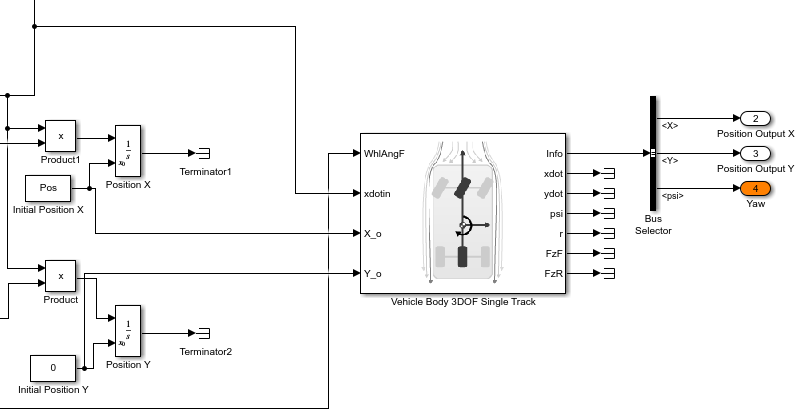

#### Bicycle Kinematic Model

- 在Vehicle3插入Bicycle Kinematic Model。

- 编辑Bicycle Kinematic Model。

- 与Vehicle Body 3DOF Single Track不同，Bicycle Kinematic Model输出的数据需要Demux而不是Bus Selector来接收。

- Vehicle Body 3DOF Single Track和Bicycle Kinematic Model不需要的输出口可以不连接Terminator而留空。

- **Vehicle Body 3DOF Single Track和Bicycle Kinematic Model的不同？**

- Wheel Base (m): 4

- Wehicle speed range (m/s): [0 12] from [-inf inf]

- Maximum steering angle (rad): pi/4 as default

- Initial State: [0; -2.5; 0]    因为初始Y位置为-2.5

            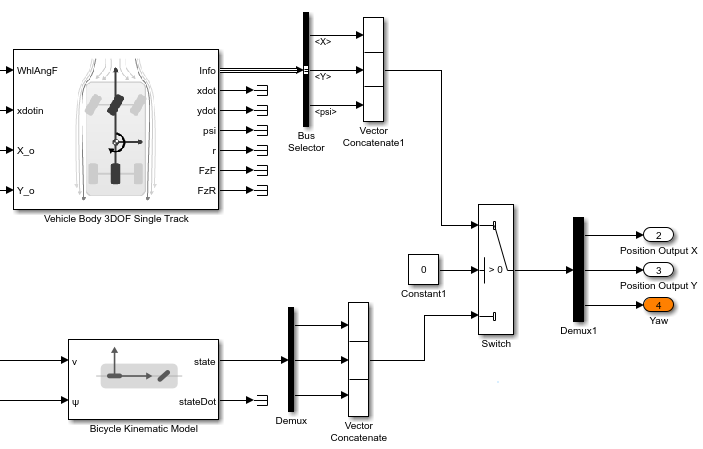

自己用switch连接的模型

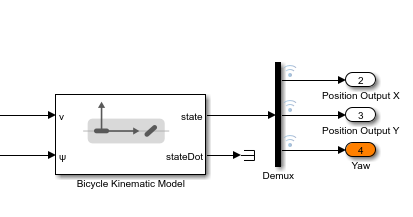

视频最终留下的模型

# Part 14: Smooth Trajectory Generation for Lane Changing

论文地址：[A_Hybrid_Approach_using_an_Adaptive_Waypoint_Generator_for_Lane-changing_Maneuver_on_Curved_Roads](https://www.researchgate.net/publication/348755604_A_Hybrid_Approach_using_an_Adaptive_Waypoint_Generator_for_Lane-changing_Maneuver_on_Curved_Roads)

代码文件：[MinimumJerkTrajectory](matlab:open('./MinimumJerkTrajectory.m'))

# Part 15: Overtaking Maneuver Implementation in Simulink